1. Considere duas vari´aveis aleat´ orias com a seguinte distribuic ¸˜ao conjunta: 

(a) Calcule as funcoes de massa de probabilidade marginais de X e Y e represente-as graficamente; 

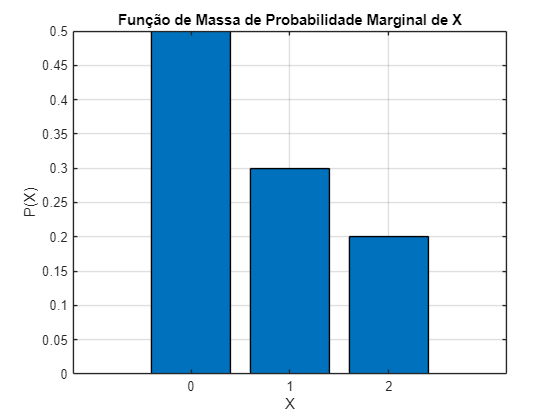

% Definindo a tabela de probabilidades conjuntas
P_XY = [0.3, 0.2, 0;
        0.1, 0.15, 0.05;
        0, 0.1, 0.1];

% Calculando a FMP marginal de X
P_X = sum(P_XY, 2);

% Calculando a FMP marginal de Y
P_Y = sum(P_XY, 1);

% Valores possíveis de X e Y
X_values = 0:2;
Y_values = 0:2;

figure;
bar(X_values, P_X);
title('Função de Massa de Probabilidade Marginal de X');
xlabel('X');
ylabel('P(X)');
grid on;

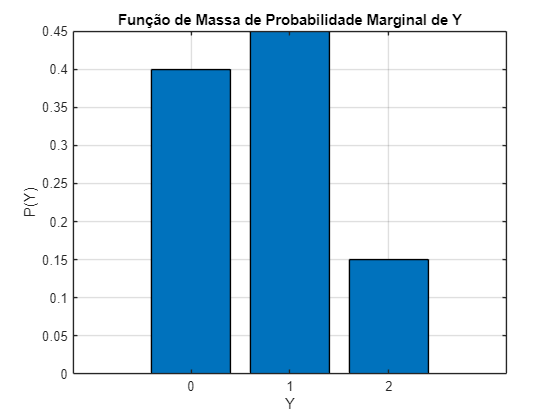


figure;
bar(Y_values, P_Y);
title('Função de Massa de Probabilidade Marginal de Y');
xlabel('Y');
ylabel('P(Y)');
grid on;

(b) Calcule a media e variancia de X e Y; 

E_X = sum(X_values .* P_X')

E_X = 0.7000

E_Y = sum(Y_values .* P_Y)

E_Y = 0.7500


% Cálculo de E(X^2) e E(Y^2)
E_X2 = sum((X_values.^2) .* P_X');
E_Y2 = sum((Y_values.^2) .* P_Y);

Var_X = E_X2 - E_X^2

Var_X = 0.6100

Var_Y = E_Y2 - E_Y^2

Var_Y = 0.4875

(c) Calcule a correlacao, covarIancia e coeficiente de correlacao entre X e Y. 

% Esperança de XY
E_XY = 0;
for i = 1:length(X_values)
    for j = 1:length(Y_values)
        E_XY = E_XY + X_values(i) * Y_values(j) * P_XY(i, j);
    end
end

Corr_XY = E_XY

Corr_XY = 0.8500


% Covariância de X e Y
Cov_XY = E_XY - E_X * E_Y

Cov_XY = 0.3250


% Coeficiente de correlação
Coef_corr_XY = Cov_XY / sqrt(Var_X * Var_Y)

Coef_corr_XY = 0.5960

2. Dada a probabilidade conjunta das variaveis X e Y:

(a) As variaveis X e Y sao independentes ? Efectue os calculos usando Matlab. 

P_XY = [1/8, 1/8, 1/24;
        0, 1/8, 1/4;
        1/24, 1/8, 1/24];

% Valores possíveis de X e Y
X_values = [-1, 0, 1];
Y_values = [-1, 0, 1];

P_X = sum(P_XY, 2);
P_Y = sum(P_XY, 1);

% Calculando as diferenças entre P(X,Y) e P(X) * P(Y)
diff_matrix = P_XY - (P_X * P_Y);

if abs(min(diff_matrix(:))) == 0
    fprintf('As variáveis X e Y são independentes.\n');
else
    fprintf('As variáveis X e Y não são independentes.\n');
end

As variáveis X e Y não são independentes.


3. Considere duas variaveis aleatorias relativas as classificacoes de uma turma de 120 alunos em duas Unidades Curriculares (ex: MPEI e POO). Designemos essas vari´aveis discretas por N1 e N2. 

(a) Gere N1 e N2 para que, antes de arredondamento para o valor inteiro mais proximo, tenham uma distribuicao Normal com as seguintes medias e variancias: media de N1 igual a 14; media de N2 20% superior a N1; variancias iguais a 1/4 da media. 

n_students = 120;  % Número total de alunos
mu_N1 = 14;       % Média de N1
mu_N2 = 1.2 * mu_N1; % Média de N2
var_N1 = mu_N1 / 4; % Variância de N1
var_N2 = mu_N2 / 4; % Variância de N2
sigma_N1 = sqrt(var_N1); % Desvio padrão de N1
sigma_N2 = sqrt(var_N2); % Desvio padrão de N2

% Gerando variáveis aleatórias N1 e N2
N1 = mu_N1 + sigma_N1 * randn(n_students, 1);
N2 = mu_N2 + sigma_N2 * randn(n_students, 1);

% Arredondando para o inteiro mais próximo
N1_rounded = round(N1);
N2_rounded = round(N2);

% Exibindo as médias e variâncias
fprintf('Média de N1: %.2f, Variância de N1: %.2f\n', mean(N1_rounded), var(N1_rounded));

Média de N1: 13.97, Variância de N1: 3.11


fprintf('Média de N2: %.2f, Variância de N2: %.2f\n', mean(N2_rounded), var(N2_rounded));

Média de N2: 17.12, Variância de N2: 4.61


(b) Obtenha e represente graficamente a funcao probabilidade de massa conjunta de N1 e N2. 

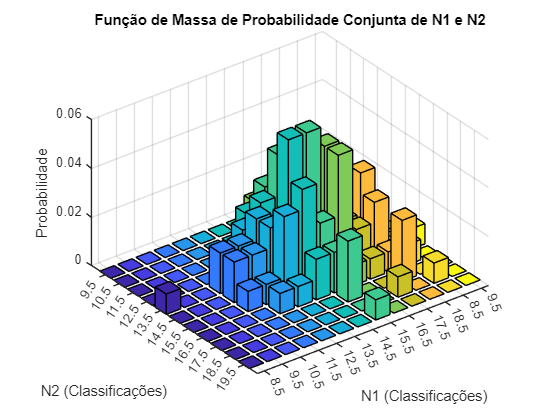

[counts, N1_edges, N2_edges] = histcounts2(N1_rounded, N2_rounded, 'Normalization', 'count');

% Calculando a função de massa de probabilidade conjunta
total_counts = sum(counts(:));
P_N1_N2 = counts / total_counts;

figure;

[N1_values, N2_values] = meshgrid(N1_edges(1:end-1), N2_edges(1:end-1));

bar3(P_N1_N2);

xlabel('N1 (Classificações)');
ylabel('N2 (Classificações)');
zlabel('Probabilidade');
title('Função de Massa de Probabilidade Conjunta de N1 e N2');

set(gca, 'XTickLabel', N1_edges(1:end-1));
set(gca, 'YTickLabel', N2_edges(1:end-1));

(c) Qual o valor do coeficiente de correlacao entre N1 e N2 ? 

correlation_coefficient = corrcoef(N1_rounded, N2_rounded);
fprintf('O coeficiente de correlação entre N1 e N2 é: %.4f\n', correlation_coefficient(1, 2));

O coeficiente de correlação entre N1 e N2 é: 0.0743


(d) N1 e N2 sao independentes ? 

P_N1 = sum(P_N1_N2, 2); % Soma ao longo das colunas para N1
P_N2 = sum(P_N1_N2, 1); % Soma ao longo das linhas para N2

% Calculando as diferenças entre P(N1,N2) e P(N1) * P(N2)
diff_matrix = P_N1_N2 - (P_N1 * P_N2);

% Verificando a independência
if all(abs(diff_matrix(:)) < 1e-6)
    fprintf('N1 e N2 são independentes.\n');
else
    fprintf('N1 e N2 não são independentes.\n');
end

N1 e N2 não são independentes.


4. Numa determinada cidade e num determinado periodo do ano a probabilidade de estar sol e 0.75 e a probabilidade de chover 0.25. As previsoes da meteorologia local acertam 100% das vezes se o tempo for de chuva mas apenas 1/3 se for um dia de sol. Um estudante atento observa que em media o meteorologista tem apenas uma taxa media de 50 %, enquanto se previsse sempre bom tempo (sol) acertaria 75% das vezes. Com base neste argumento candidata-se ao lugar, mas um responsavel que sabia um pouco de probabilidades rejeita a candidatura. Explique porque? 

Sugestao: Comece por criar a tabela com a funcao massa de probabilidade conjunta.

P_S = 0.75;      % Probabilidade de sol
P_C = 0.25;      % Probabilidade de chuva

P_E_given_S = 1/3; % Probabilidade de acertar se está sol
P_E_given_C = 1;    % Probabilidade de acertar se está chovendo

% Calcular as probabilidades conjuntas
P_E_and_S = P_E_given_S * P_S;   % Probabilidade de previsão boa e estar sol
P_notE_and_S = (2/3) * P_S;       % Probabilidade de previsão de chuva e estar sol
P_E_and_C = P_E_given_C * P_C;    % Probabilidade de previsão boa e chover
P_notE_and_C = 0;                  % Probabilidade de previsão de chuva e chover

% Tabela da função de massa de probabilidade conjunta
P_XY = [P_E_and_S, P_E_and_C; P_notE_and_S, P_notE_and_C];

fprintf('Tabela da Função de Massa de Probabilidade Conjunta:\n');

Tabela da Função de Massa de Probabilidade Conjunta:


disp(array2table(P_XY, 'VariableNames', {'Previsao Boa', 'Previsao Chuva'}, 'RowNames', {'Sol', 'Chuva'}));

             Previsao Boa    Previsao Chuva
             ____________    ______________

    Sol          0.25             0.25     
    Chuva         0.5                0     




P_E = sum(P_XY(1, :));      
P_notE = sum(P_XY(2, :));   